## Задание 4. (Необязательное) Наблюдатель пониженного порядка. 

Начальные условия на задание:

A = [5 -7 -5 1;
    -7 5 -1 5;
    -5 -1 5 7;
    1 5 7 5]

A =      5    -7    -5     1
    -7     5    -1     5
    -5    -1     5     7
     1     5     7     5



B = [5 7 1 9]'

B =      5
     7
     1
     9



C = [0 1 0 0; 
    1 0 0 0]

C =      0     1     0     0
     1     0     0     0



D = [4 2]'

D =      4
     2


Найти собственные числа матрицы A и определить управляемость каждого из них. Сделать вывод об управляемости и стабилизируемости системы.

U = [B , A*B , A^2 * B, A^3 * B];
U = ctrb(A, B);
rank(U)

ans = 4



V = obsv(A, C)

V =            0           1           0           0
           1           0           0           0
          -7           5          -1           5
           5          -7          -5           1
         -60         100          60          36
         100         -60         -36         -60
       -1264        1040         752        1040
        1040       -1264       -1040        -752


V = [C ; C*A ; C*A^2 ; C*A^3];
rank(V)

ans = 4

**Управляемая + стабилизируема || Наблюдаема+обнаруживаема**

eig(A)

ans =    -8.0000
    4.0000
    8.0000
   16.0000


l1 = -8; l2 = 4; l3 = 8; l4 = 16;

[A - eye(4).*l1 , B]

ans =     13    -7    -5     1     5
    -7    13    -1     5     7
    -5    -1    13     7     1
     1     5     7    13     9


[A - eye(4).*l2 , B]

ans =      1    -7    -5     1     5
    -7     1    -1     5     7
    -5    -1     1     7     1
     1     5     7     1     9


[A - eye(4).*l3 , B]

ans =     -3    -7    -5     1     5
    -7    -3    -1     5     7
    -5    -1    -3     7     1
     1     5     7    -3     9


[A - eye(4).*l4 , B]

ans =    -11    -7    -5     1     5
    -7   -11    -1     5     7
    -5    -1   -11     7     1
     1     5     7   -11     9



rank([A - eye(4).*l1 , B])

ans = 4

rank([A - eye(4).*l2 , B])

ans = 4

rank([A - eye(4).*l3 , B])

ans = 4

rank([A - eye(4).*l4 , B])

ans = 4

[P,Aj] = jordan(A);
[P2, Aj2] = cdf2rdf(P,Aj);
double(P2)

ans =     -1    -1     1     1
     1    -1    -1     1
     1    -1     1    -1
     1     1     1     1


double(Aj2)

ans =     16     0     0     0
     0    -8     0     0
     0     0     8     0
     0     0     0     4



P1(:,1)=real(P(:,1)); 
P1(:,2)=imag(P(:,2)); 
P1(:,3)=real(P(:,3)); 

G = [-1 0 0 0;
      0 -0.5 1 0;
      0   0  -0.5 1;
      0    0   0 -0.5]

G =    -1.0000         0         0         0
         0   -0.5000    1.0000         0
         0         0   -0.5000    1.0000
         0         0         0   -0.5000


%%%%%%%%%%%%%%%% CONTROL - find K
Y = [1 1 1 1]

Y =      1     1     1     1


cvx_begin sdp
variable P(4,4)
A*P - P*G == B*Y;
cvx_end

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.6e-01|5.1e+02|9.2e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.987|7.2e-10|6.9e+00|2.7e+02| 0.000000e+00  1.408943e-02| 0:0:01| chol  1  1 
 2|1.000|0.990|2.2e-09|7.7e-02|8.4e-01| 0.000000e+00  3.383033e-03| 0:0:01| chol  1  1 
 3|1.000|0.997|8.7e-10|1.3e-03|6.4e-03| 0.000000e+00  1.218631e-03| 0:0:01| chol  1  1 
 4|1.000|1.00

K = -Y*pinv(P)

K =     4.2321   -3.9908   -1.2129   -1.6125


eig(A+B*K)

ans =   -0.4967 + 0.0000i
  -0.5017 + 0.0029i
  -0.5017 - 0.0029i
  -1.0000 + 0.0000i


%%%%%%%%%%%%%%%%

% lambdas=[-3,-3]; LOW
% G = [-3 1 0 0 ;
%       0 -3 1 0;
%       0  0 -3 1;
%       0   0  0  -3]
G = [-20 1 ;
      0 -20]

G =    -20     1
     0   -20


eig(G)

ans =    -20
   -20



%%%%%%%%%%%%%%%% OBSERVE - find low-dimension Q
Y = [1 0; 0 1]'

Y =      1     0
     0     1


% Q(4,4)
cvx_begin sdp
variable Q(2,4)
G * Q - Q * A == Y*C;
cvx_end

 
Calling SDPT3 4.0: 8 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of linear var  =  1
 dim. of free   var  =  8 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.9e-01|6.2e+02|3.9e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.989|1.9e-10|6.8e+00|8.8e+01| 0.000000e+00  8.538464e-06| 0:0:00| chol  1  1 
 2|1.000|0.991|3.4e-10|7.4e-02|2.3e-01| 0.000000e+00  2.213591e-06| 0:0:00| chol  1  1 
 3|1.000|1.000|1.4e-10|1.0e-03|2.6e-03| 0.000000e+00  1.087802e-06| 0:0:00| chol  1  1 
 4|1.000|1.000|

Q

Q =    -0.0181   -0.0488   -0.0099    0.0136
   -0.0471   -0.0154   -0.0124    0.0084


% L = pinv(Q)*Y
% eig(A+L*C)
%%%%%%%%%%%%%%%%
N = [C ; Q]

N =          0    1.0000         0         0
    1.0000         0         0         0
   -0.0181   -0.0488   -0.0099    0.0136
   -0.0471   -0.0154   -0.0124    0.0084



x0 = [1 1 1 1]';        % plant
% x_hat0 = [0 0 0 0]';   % observer
x_hat0 = [0 0]';   % observer
simTimeStart = 0;
simTimeEnd = 25;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';

data.time= time;
modelName = 'model_observer_down_controller'; 
load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

Found algebraic loop containing: 
model_observer_down_controller/Gain5
model_observer_down_controller/Gain5
model_observer_down_controller/Gain8
model_observer_down_controller/Gain4
model_observer_down_controller/Sum2 (algebraic variable)
model_observer_down_controller/Gain
model_observer_down_controller/Sum (algebraic variable)


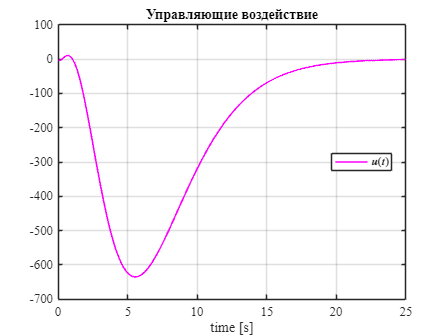


time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.5); 
grid on;
xlabel('time [s]');
grid on;
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')

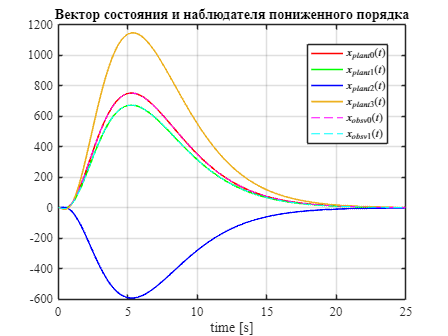


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.5); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.5); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.5); 
plot(time, x_plant(:,4), 'Color', '#EDB120', 'LineWidth', 1.5); 
plot(time, x_obsv(:,1), 'magenta--', 'LineWidth', 1.0);
plot(time, x_obsv(:,2), 'cyan--', 'LineWidth', 1.0); 
grid on;
title('Вектор состояния и наблюдателя пониженного порядка')
xlabel('time [s]');
grid on;
legend('$x_{plant0}(t)$','$x_{plant1}(t)$', ...
    '$x_{plant2}(t)$','$x_{plant3}(t)$', ...
            '$x_{obsv0}(t)$','$x_{obsv1}(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("low_dim_compare1");

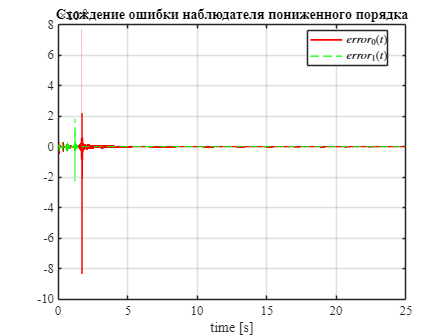


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, error(:,1), 'r', 'LineWidth', 1.5); hold on
plot(time, error(:,2), 'g--', 'LineWidth', 1.0); 
grid on;
title('Схождение ошибки наблюдателя пониженного порядка')
xlabel('time [s]');                                   
legend('$error_0(t)$','$error_1(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');

Теперь нужно синтезировать регулятор + наблюдателя для пары желаемых спектров, выбираем сами...

Для каждого спектра...

[P,Aj] = jordan(A);
[P2, Aj2] = cdf2rdf(P,Aj);
double(P2)

ans =     -1    -1     1     1
     1    -1    -1     1
     1    -1     1    -1
     1     1     1     1


double(Aj2)

ans =     16     0     0     0
     0    -8     0     0
     0     0     8     0
     0     0     0     4



P1(:,1)=real(P(:,1)); 
P1(:,2)=imag(P(:,2)); 
P1(:,3)=real(P(:,3)); 

% lambdas=[-1,-4,-4, -4];
G = [-1 0 0 0;
      0 -4 1 0;
      0   0  -4 1;
      0    0   0 -4]

G =     -1     0     0     0
     0    -4     1     0
     0     0    -4     1
     0     0     0    -4


%%%%%%%%%%%%%%%% CONTROL - find K
Y = [1 1 1 1]

Y =      1     1     1     1


cvx_begin sdp
variable P(4,4)
A*P - P*G == B*Y;
cvx_end

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.6e-01|6.0e+02|1.1e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.987|3.5e-10|7.8e+00|3.0e+02| 0.000000e+00  6.035597e-03| 0:0:00| chol  1  1 
 2|1.000|0.990|1.0e-09|8.6e-02|8.3e-01| 0.000000e+00  1.481438e-03| 0:0:00| chol  1  1 
 3|1.000|0.997|4.2e-10|1.3e-03|5.5e-03| 0.000000e+00  5.728367e-04| 0:0:00| chol  1  1 
 4|1.000|1.00

K = -Y*pinv(P)

K =     8.5179   -8.9138   -0.8756   -1.3686


eig(A+B*K)

ans =   -1.0000 + 0.0000i
  -3.9996 + 0.0000i
  -4.0002 + 0.0004i
  -4.0002 - 0.0004i


%%%%%%%%%%%%%%%%

% lambdas=[-3,-3]; LOW
% G = [-3 1 0 0 ;
%       0 -3 1 0;
%       0  0 -3 1;
%       0   0  0  -3]
G = [-3 1 ;
      0 -3]

G =     -3     1
     0    -3


eig(G)

ans =     -3
    -3



%%%%%%%%%%%%%%%% OBSERVE - find low-dimension Q
Y = [1 0; 0 1]'

Y =      1     0
     0     1


% Q(4,4)
cvx_begin sdp
variable Q(2,4)
G * Q - Q * A == Y*C;
cvx_end

 
Calling SDPT3 4.0: 8 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of linear var  =  1
 dim. of free   var  =  8 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.9e-01|2.8e+02|1.8e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.989|4.3e-10|3.2e+00|4.2e+01| 0.000000e+00  4.995945e-05| 0:0:00| chol  1  1 
 2|1.000|0.992|1.6e-09|3.4e-02|1.2e-01| 0.000000e+00  1.296737e-05| 0:0:00| chol  1  1 
 3|1.000|1.000|4.8e-10|1.0e-03|2.6e-03| 0.000000e+00  6.529171e-06| 0:0:00| chol  1  1 
 4|1.000|1.000|

Q

Q =     0.0323   -0.0339    0.0890   -0.0726
   -0.0216    0.0502    0.0761   -0.0953


% L = pinv(Q)*Y
% eig(A+L*C)
%%%%%%%%%%%%%%%%
N = [C ; Q]

N =          0    1.0000         0         0
    1.0000         0         0         0
    0.0323   -0.0339    0.0890   -0.0726
   -0.0216    0.0502    0.0761   -0.0953


x0 = [1 1 1 1]';        % plant
% x_hat0 = [0 0 0 0]';   % observer
x_hat0 = [0 0]';   % observer
simTimeStart = 0;
simTimeEnd = 10;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';

data.time= time;
modelName = 'model_observer_down_controller'; 
load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

Found algebraic loop containing: 
model_observer_down_controller/Gain5
model_observer_down_controller/Gain5
model_observer_down_controller/Gain8
model_observer_down_controller/Gain4
model_observer_down_controller/Sum2 (algebraic variable)
model_observer_down_controller/Gain
model_observer_down_controller/Sum (algebraic variable)


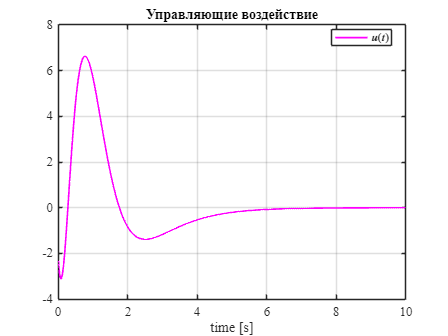


time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.5); 
grid on;
xlabel('time [s]');
grid on;
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("low_dim_u1");

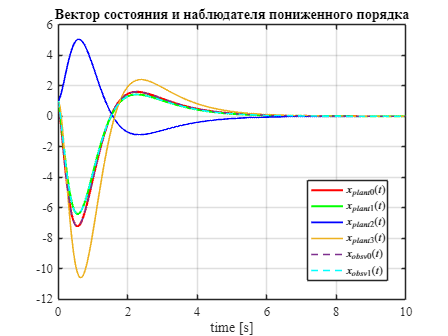


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 2.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 2.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.5); 
plot(time, x_plant(:,4), 'Color', '#EDB120', 'LineWidth', 1.5); 
plot(time, x_obsv(:,1), 'Color', '#7E2F8E', 'LineStyle', '--', 'LineWidth', 1.5);
plot(time, x_obsv(:,2), 'cyan--', 'LineWidth', 1.5); 
grid on;
title('Вектор состояния и наблюдателя пониженного порядка')
xlabel('time [s]');
grid on;
legend('$x_{plant0}(t)$','$x_{plant1}(t)$', ...
    '$x_{plant2}(t)$','$x_{plant3}(t)$', ...
            '$x_{obsv0}(t)$','$x_{obsv1}(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("low_dim_compare1");

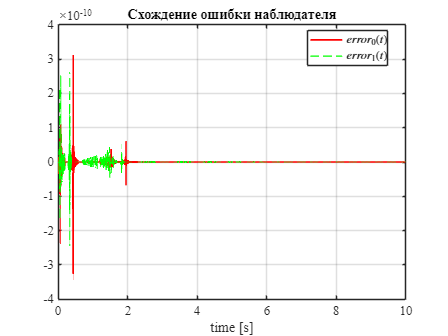


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, error(:,1), 'r', 'LineWidth', 1.5); hold on
plot(time, error(:,2), 'g--', 'LineWidth', 1.0); 
grid on;
title('Схождение ошибки наблюдателя')
xlabel('time [s]');                                   
legend('$error_0(t)$','$error_1(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("low_dim_error1");

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab8\latex8\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end